% Paths and Parameters
imageFolder = 'training_img_scalograms';  % Folder with spectrogram images
labelFile = 'labels.csv';  % CSV file with labels

% Load Labels from CSV
labelsTbl = readtable(labelFile);  % Now reads with headers
labelsTbl.file_name = strcat(labelsTbl.file_name, '.png');  % Append .png to filenames

% Create imageDatastore for images
imds = imageDatastore(imageFolder, 'FileExtensions', '.png');

% Link labels to images using file names
[~, fileNames] = fileparts(imds.Files);
[~, labelFileNames] = fileparts(labelsTbl.file_name);
[isMember, idx] = ismember(fileNames, labelFileNames);
imds.Files = imds.Files(isMember);  % Filter files that have labels
imds.Labels = categorical(labelsTbl.target(idx(isMember)));  % Set labels from CSV

% Resize images to match network input size
imageSize = [256 256];  % Resize to 256x256
imds.ReadFcn = @(x) imresize(imread(x), imageSize);

% Split Data into Training and Validation Sets
[imdsTrain, imdsValidation] = splitEachLabel(imds, 0.8, 'randomized');

## Benchmark CNN

layers = [
    imageInputLayer([256 256 3])  % Input size 256x256 with 3 color channels
    
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 64, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 128, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 128, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    fullyConnectedLayer(512)
    reluLayer
    
    fullyConnectedLayer(2)  % Two classes: noisy (1) and non-noisy (0)
    softmaxLayer
    classificationLayer];

## Specify Training Options

options = trainingOptions('adam', ...
    'InitialLearnRate', 1e-4, ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 32, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', imdsValidation, ...
    'ValidationFrequency', 10, ...
    'Verbose', true, ...
    'Plots', 'training-progress', ...
    'ExecutionEnvironment', 'gpu');  % Specify to use GPU

## Train the Network

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:11 |       81.25% |       94.94% |       0.5269 |       1.7347 |      1.0000e-04 |
|       1 |          10 |       00:00:15 |       96.88% |       94.62% |       0.1272 |       0.2767 |      1.0000e-04 |
|       1 |          20 |       00:00:18 |       90.62% |       94.94% |       0.5682 |       0.2932 |      1.0000e-04 |
|       1 |          30 |       00:00:21 |       93.75% |       94.62% |       0.1630 |       0.2159 |      1.0000

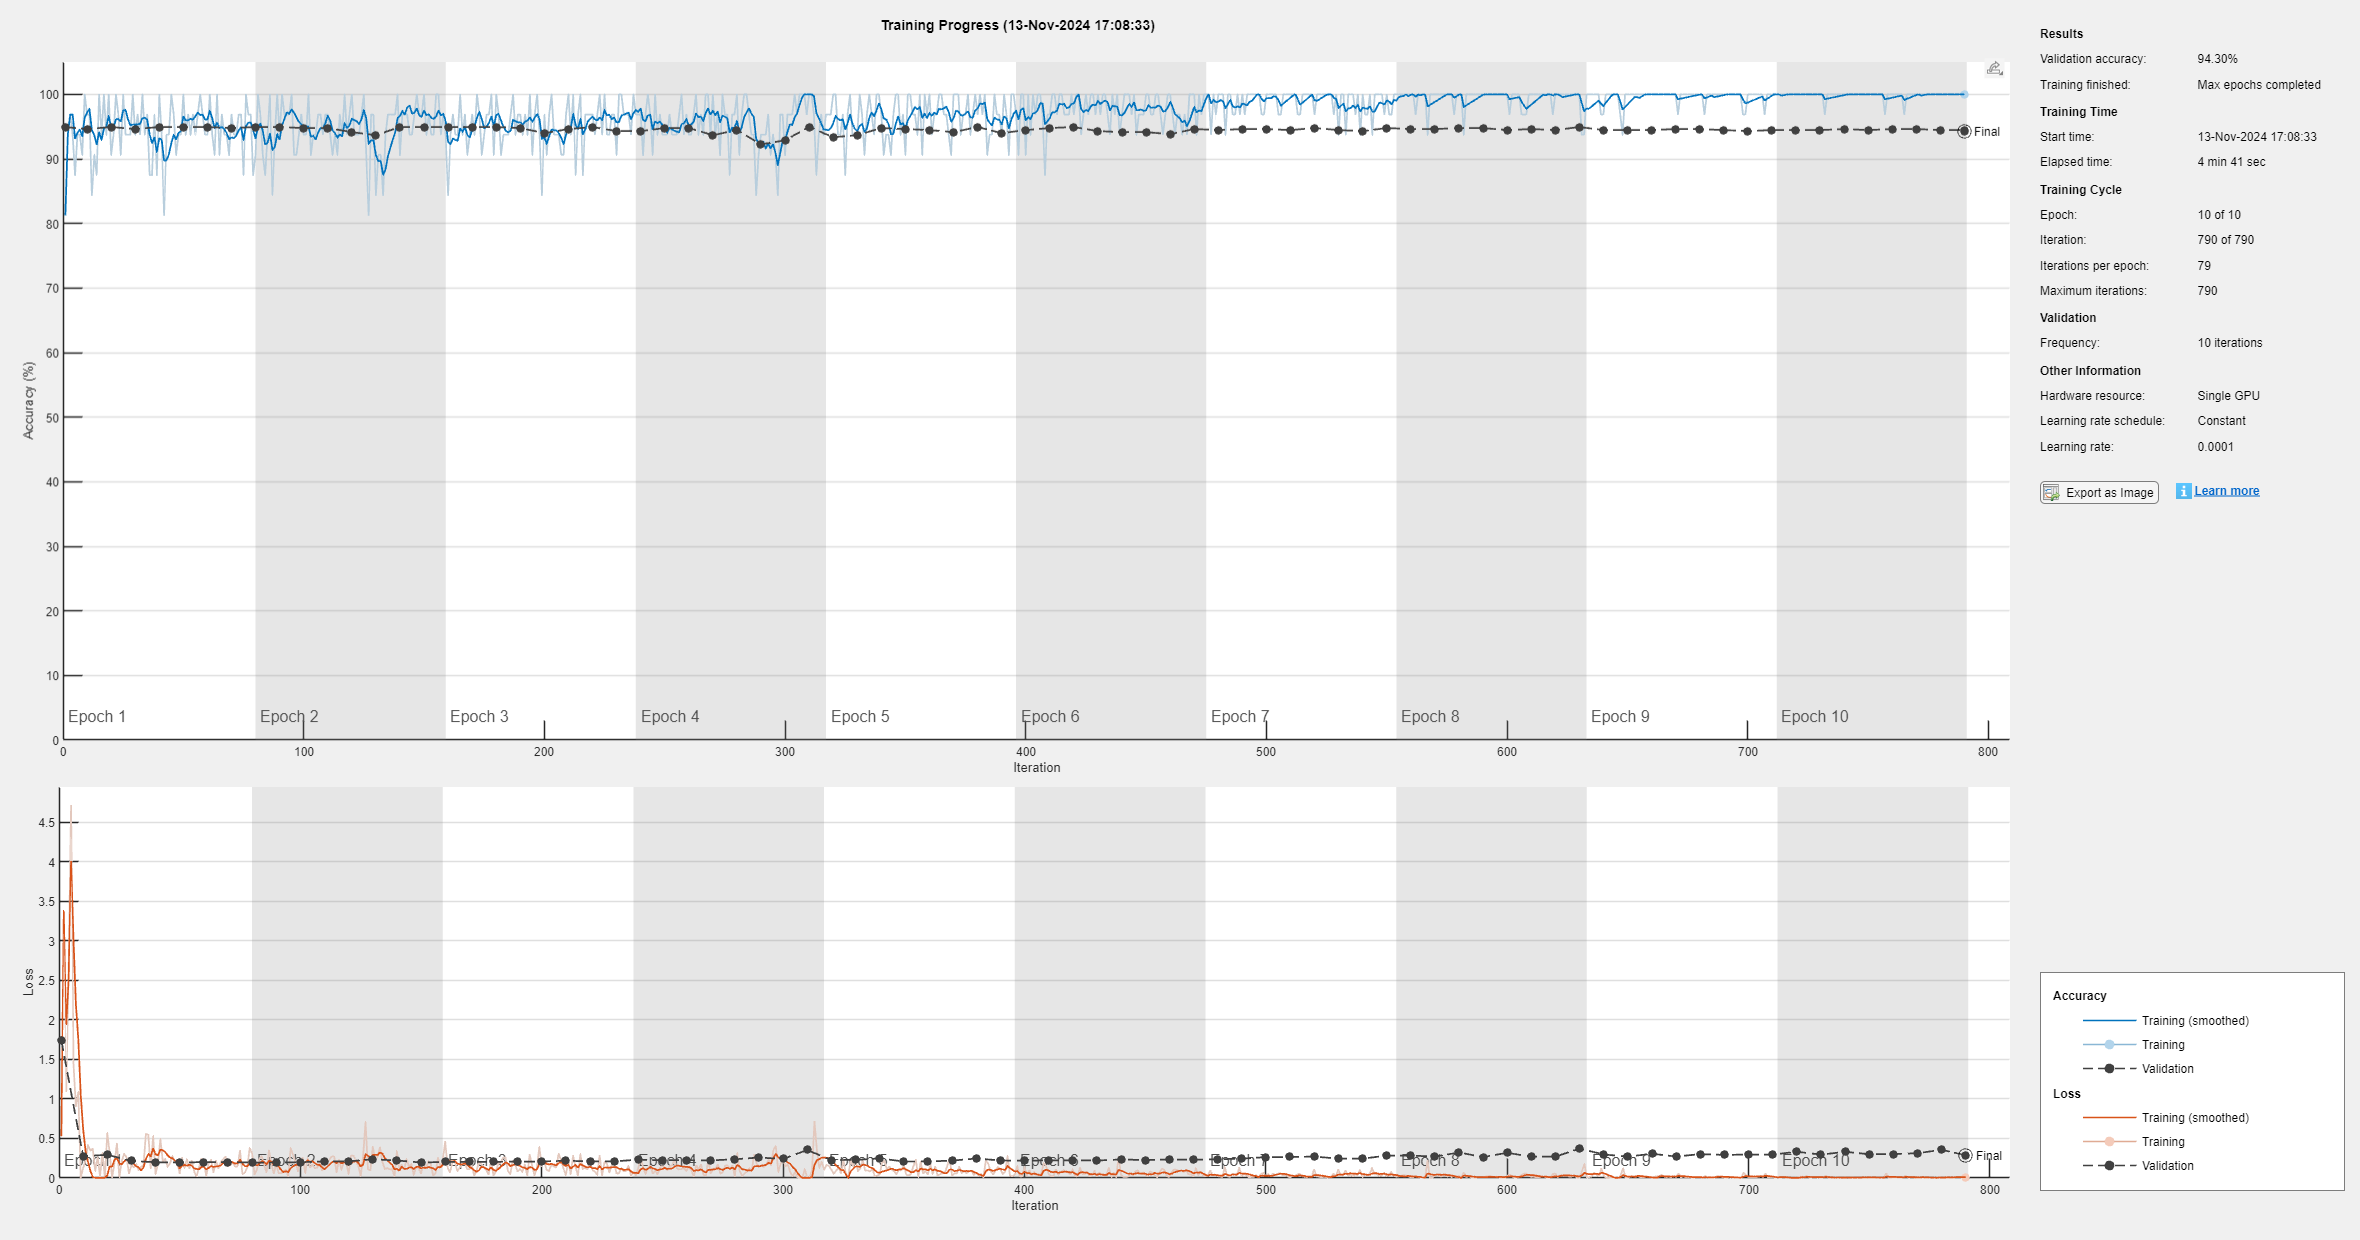

net = trainNetwork(imdsTrain, layers, options);

## Evaluation

Predict probabilities for the validation set using `predict`

YPredScores = predict(net, imdsValidation);

% Predict class labels using `classify`
YPred = classify(net, imdsValidation);
YValidation = imdsValidation.Labels;

## Plot the AUC-ROC Curve

Assuming the positive class is "1" (i.e., noise)

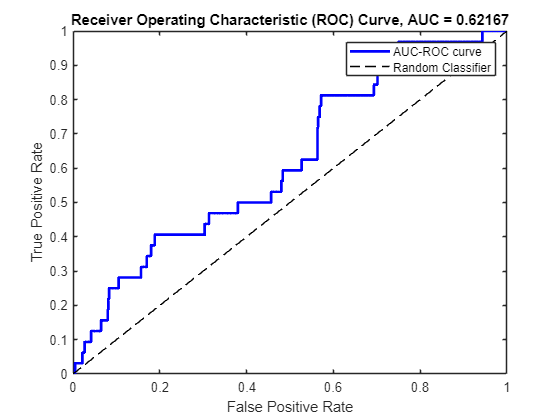

positiveClass = categorical(1);  % Modify if your positive class is different
scores = YPredScores(:, find(net.Layers(end).Classes == positiveClass));

% Convert categorical labels to numeric for ROC computation
YValidationNumeric = double(YValidation == positiveClass);

% Compute the ROC curve and AUC
[fpr, tpr, ~, aucValue] = perfcurve(YValidationNumeric, scores, 1);

% Plot the ROC curve
figure;
plot(fpr, tpr, 'b-', 'LineWidth', 2);
hold on;
plot([0 1], [0 1], 'k--');  % Diagonal line for random classifier
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title(['Receiver Operating Characteristic (ROC) Curve, AUC = ' num2str(aucValue)]);
legend('AUC-ROC curve', 'Random Classifier');
hold off;

## Plot the Confusion Matrix

Confusion matrix between true labels and predicted labels

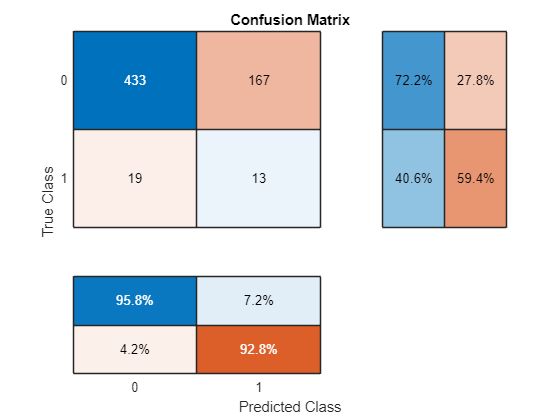

%% Define a Threshold for Classification
threshold = 0.01;  % Set your desired threshold here (e.g., 0.7)

% Predict probabilities for the validation set using `predict`
YPredScores = predict(net, imdsValidation);

% Assuming the positive class is "1" (i.e., noise)
positiveClass = categorical(1);  % Modify if your positive class is different
scores = YPredScores(:, find(net.Layers(end).Classes == positiveClass));

% Apply the threshold to generate binary predictions
YPredAdjusted = scores >= threshold;  % Logical array based on threshold
YPredAdjusted = categorical(YPredAdjusted, [0, 1], {'0', '1'});  % Convert to categorical

%% Plot the Confusion Matrix with Adjusted Threshold
YValidation = imdsValidation.Labels;

% Plot confusion matrix
figure;
confusionchart(YValidation, YPredAdjusted, 'Title', ['Confusion Matrix'], ...
               'RowSummary', 'row-normalized', 'ColumnSummary', 'column-normalized');